# 1110_课堂内容

## matlab变量和矩阵基本操作

a=123456789101121314

a =  123456789101121312.00


% format命令进行控制，只影响结果显示，不影响其存储
format bank
disp(a)

 123456789101121312.00



% 一般来讲Matlab以双子长浮点数（双精度）执行运算

% save命令讲工作区中全部变量储存到文件中
save


正在保存到: C:\Users\Administrator\Documents\MATLAB\matlab.mat



% load 默认从matlab.mat中读取数据

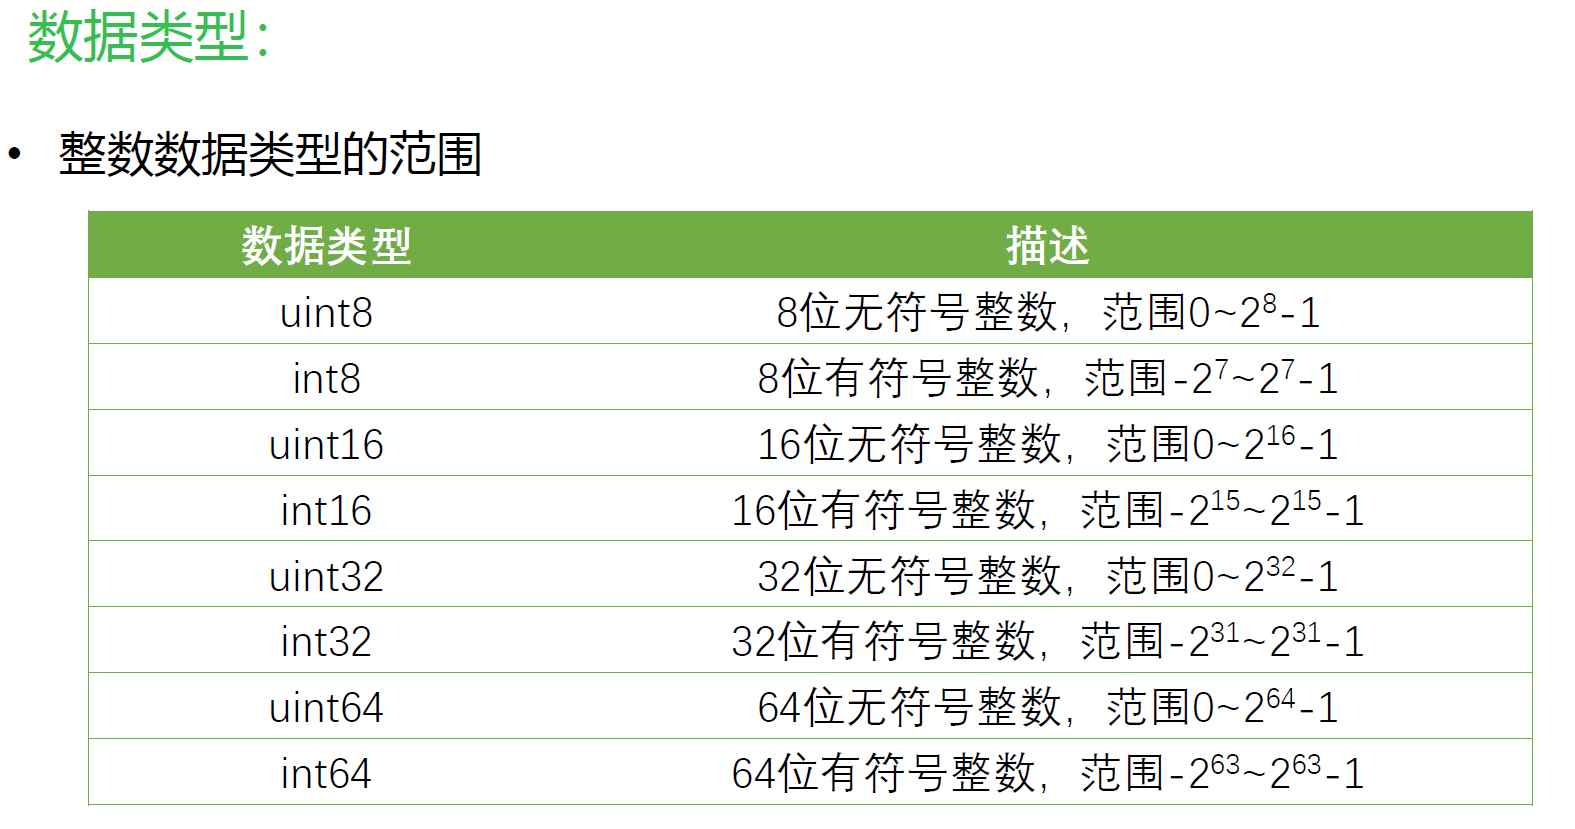

**数据类型的范围：**

intmax('int16')

ans = int16
   32767


intmin('uint32')

ans = uint32
   0


intmax('uint8')

ans = uint8
   255


a=uint8(10);
a=a+254;
disp(a) % 255

   255



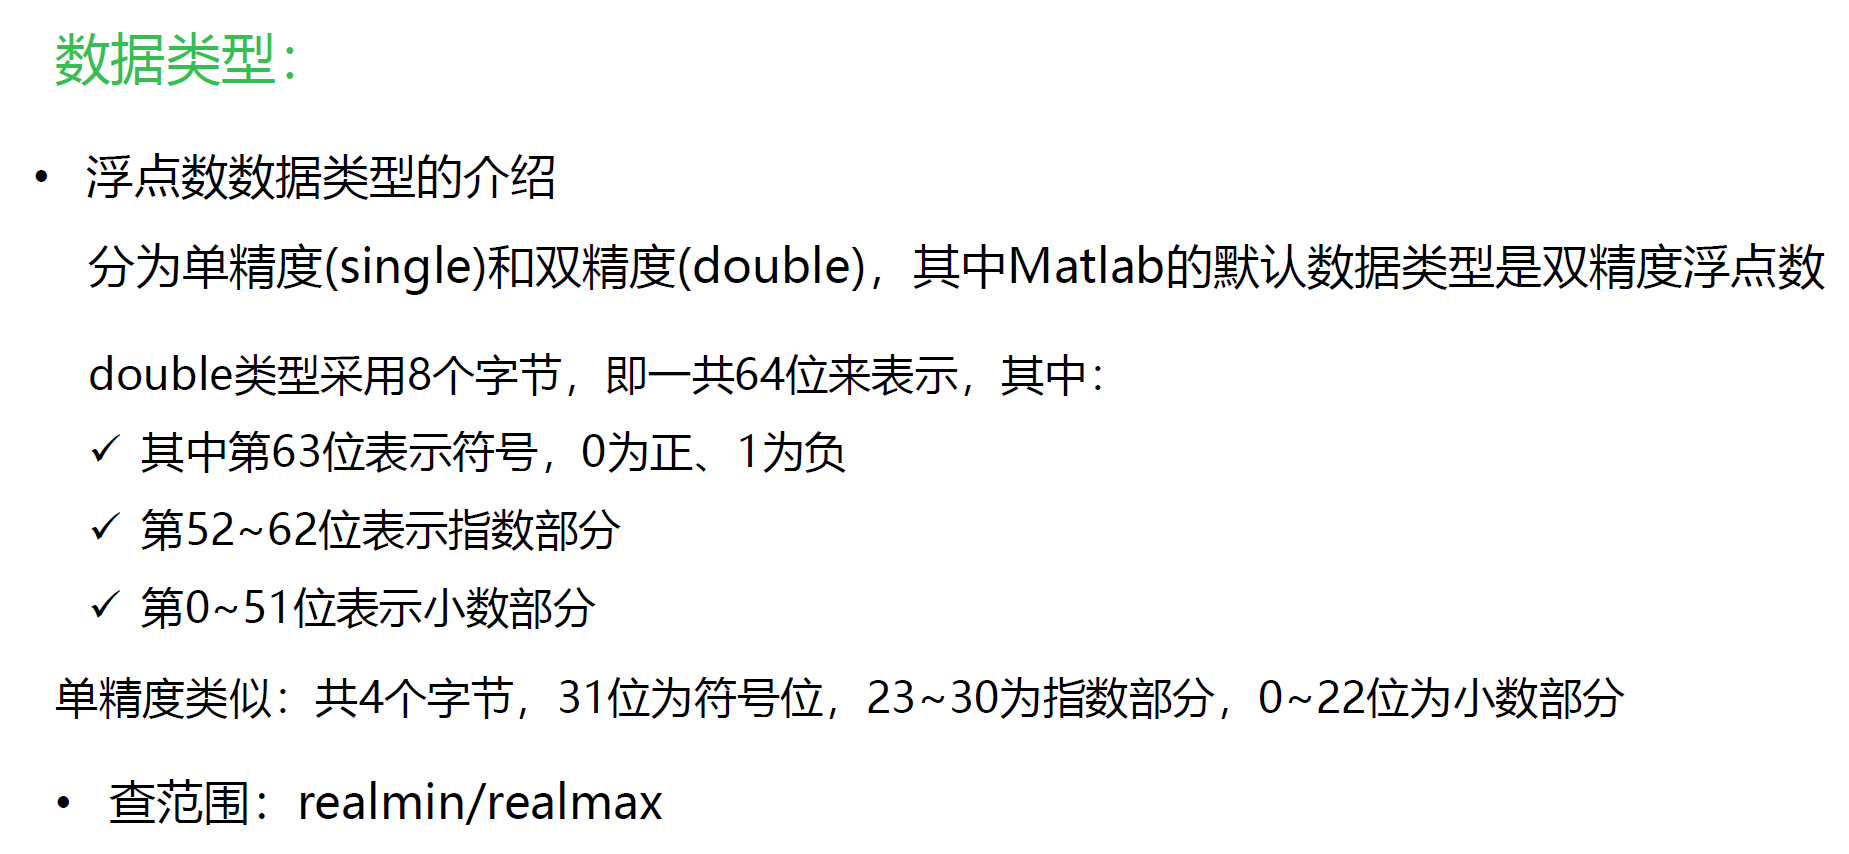

realmin("single")

ans = single
          0.00


realmin("double")

ans =           0.00


1/0 %inf表示无穷大

ans =            Inf


0/0 % NaN表示未定义或不可表示

ans =            NaN


**字符串：**

% ""和''的区别
a1='abc';
size(a1)

ans =           1.00          3.00


a2="abc";
size(a2)

ans =           1.00          1.00


% ""和''的区别
disp('a'+'b') 

        195.00



disp("a"+"b")

ab


% whos函数查看当前工作区的所有变量

**关系运算符：**

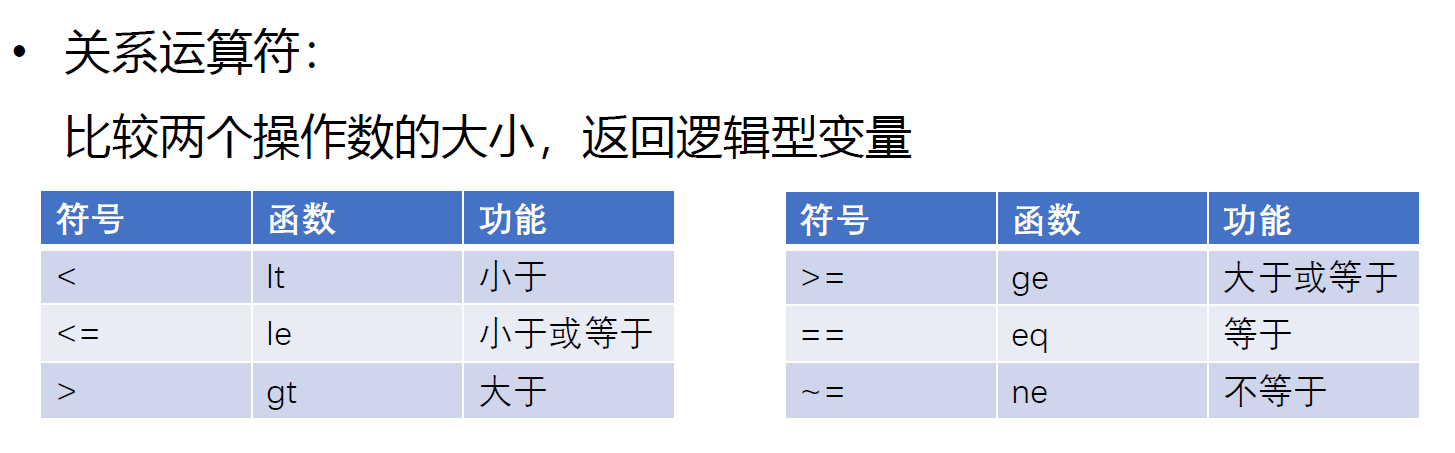

a=1;b=2;
lt(a,b)

ans = logical
   1


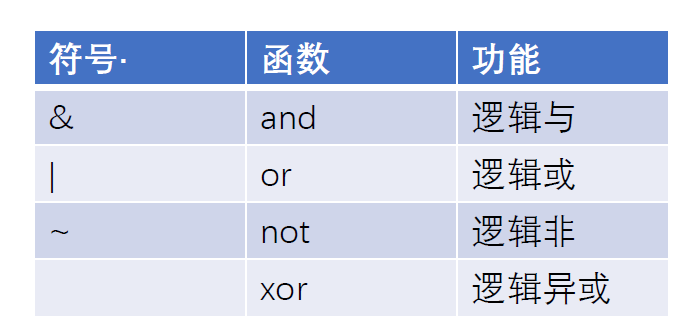

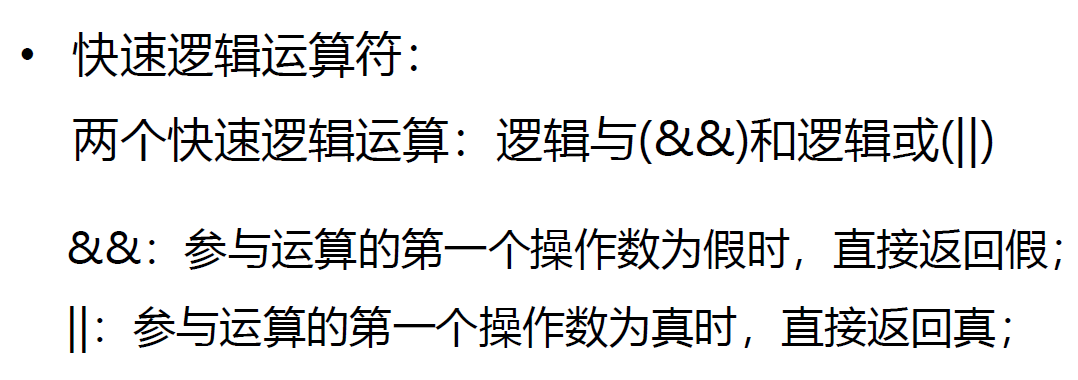

## 矩阵

a=[1,2,3,4]

a =           1.00          2.00          3.00          4.00


b=[1;2;3;4]

b =           1.00
          2.00
          3.00
          4.00


**函数生成矩阵：**

ones(3) % 1阵

ans =           1.00          1.00          1.00
          1.00          1.00          1.00
          1.00          1.00          1.00


zeros(3) % 0阵

ans =              0             0             0
             0             0             0
             0             0             0


eye(3) % 单位阵

ans =           1.00             0             0
             0          1.00             0
             0             0          1.00


magic(3) % 魔方阵（每一行每一列元素和相等）

ans =           8.00          1.00          6.00
          3.00          5.00          7.00
          4.00          9.00          2.00


rand(3,3) % 随机数矩阵

ans =           0.34          0.75          0.70
          0.59          0.26          0.89
          0.22          0.51          0.96


**矩阵部分删除：**

A=[1 2 3 4;5 6 7 8;9 10 11 12];
% 将某行和某列赋值为空值，完成删除
A(:,2)=[];
A

A =           1.00          3.00          4.00
          5.00          7.00          8.00
          9.00         11.00         12.00


% 矩阵元素的修改（抽取）
% 对角矩阵diag
% 三角矩阵tril/triu
diag(A)

ans =           1.00
          7.00
         12.00


tril(A) % 取下三角

ans =           1.00             0             0
          5.00          7.00             0
          9.00         11.00         12.00


triu(A) % 取上三角

ans =           1.00          3.00          4.00
             0          7.00          8.00
             0             0         12.00


A = reshape(A,1,9)

A =           1.00          5.00          9.00          3.00          7.00         11.00          4.00          8.00         12.00


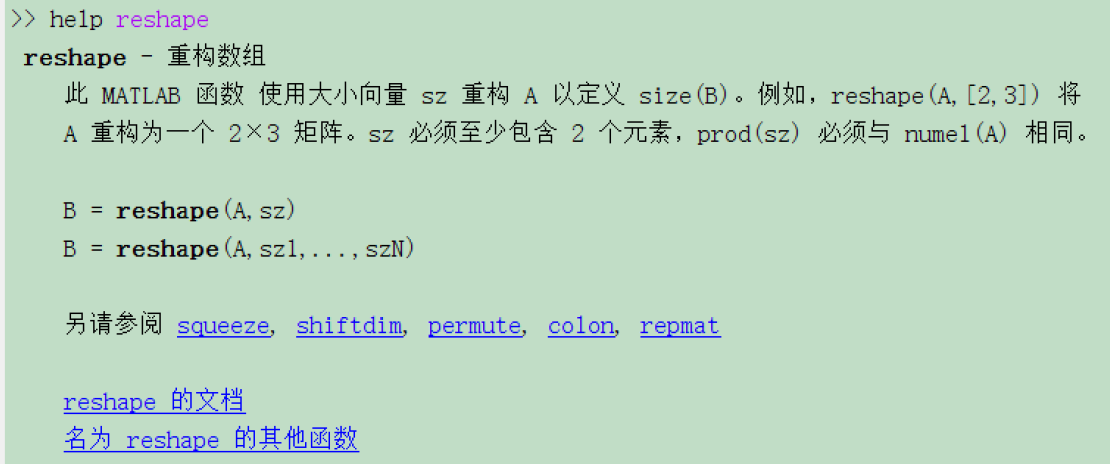

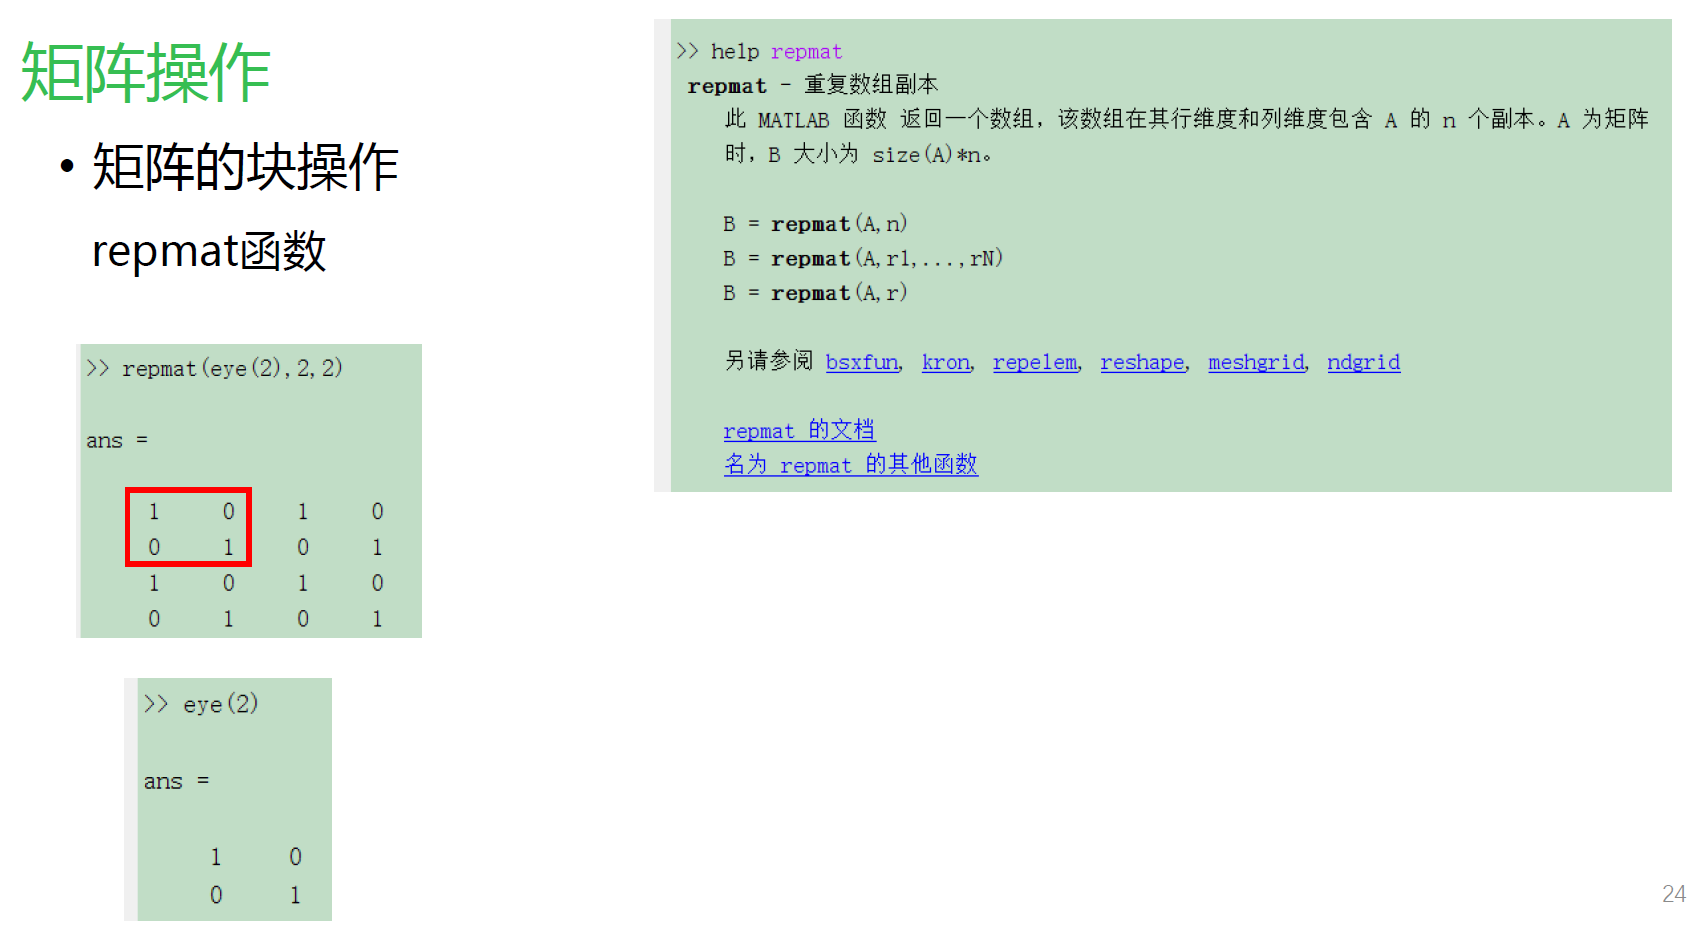

**矩阵操作：**

A=[0.1,-0.1,0.2]

A =           0.10         -0.10          0.20


floor(A) % 向下取整

ans =              0         -1.00             0


ceil(A) % 向上取整

ans =           1.00             0          1.00


round(A) % 四舍五入

ans =              0             0             0


fix(A) % 按零近方向取整

ans =              0             0             0


rem(A,3) % 取余数

ans =           0.10         -0.10          0.20


**索引：**

A=[11,21,6;12,20,9;10,22,3]

A =          11.00         21.00          6.00
         12.00         20.00          9.00
         10.00         22.00          3.00


A(6) % 从列开始数的

ans =          22.00


A([1,3,5])

ans =          11.00         10.00         20.00


A([1,3;1,3])

ans =          11.00         10.00
         11.00         10.00


A(3,2) % 第三行第二个元素

ans =          22.00


A([1,3],[1,3])

ans =          11.00          6.00
         10.00          3.00


**冒号算子：**

B = [1:5;2:3:15;-2:1:2]

B =           1.00          2.00          3.00          4.00          5.00
          2.00          5.00          8.00         11.00         14.00
         -2.00         -1.00             0          1.00          2.00


% [begin:step:end] % 双闭
A = [1,2,3;4,5,6;7,8,9]

A =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


% A(3,:)表示第三行的全部元素
% A(:,3)表示的是第三列的全部元素
% A(3,:)=0;整行赋值
% A(3,:)=[]整行删除

**矩阵运算：**

format short
A = [1,5,9;3,4,7;6,8,2]

A =      1     5     9
     3     4     7
     6     8     2


A' % 矩阵的转置

ans =      1     3     6
     5     4     8
     9     7     2


det(A) % 行列式的计算

ans = 132

inv(A) % 矩阵的逆

ans =    -0.3636    0.4697   -0.0076
    0.2727   -0.3939    0.1515
         0    0.1667   -0.0833


A*inv(A) 

ans =     1.0000    0.0000   -0.0000
         0    1.0000    0.0000
         0   -0.0000    1.0000


% 矩阵的范数
norm(A,2)

ans = 15.4450

% 矩阵的秩
rank(A)

ans = 3

% 矩阵的特征向量 eighanshu 
eig(A)

ans =    14.9915
   -1.3197
   -6.6718


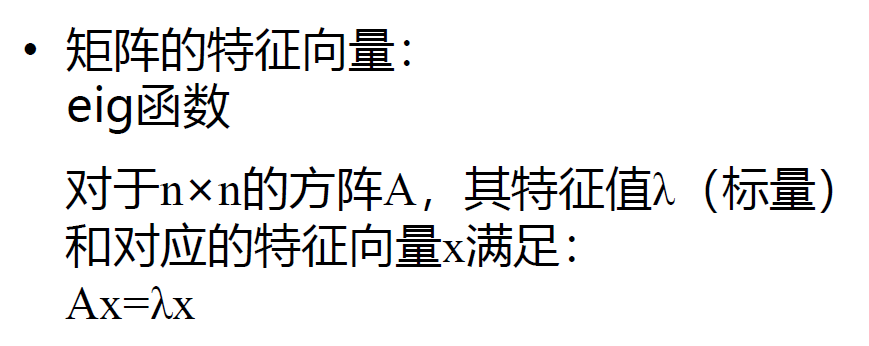

**矩阵的四则运算：**

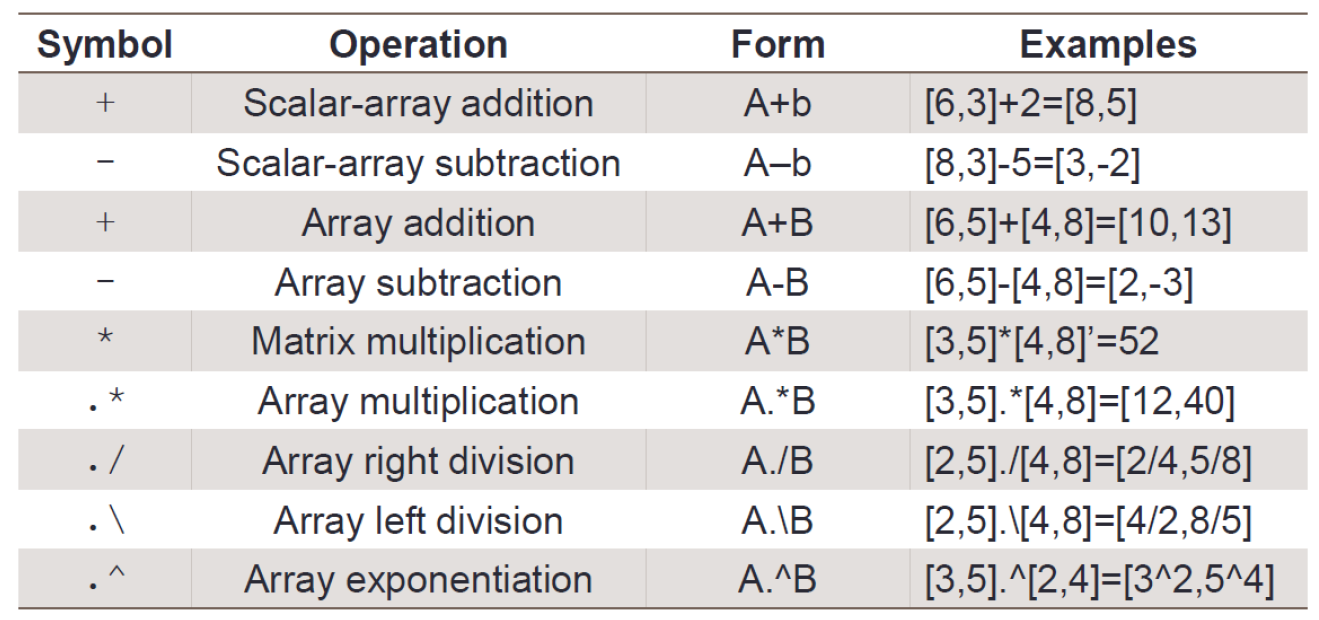

**矩阵运算相关函数：**

A =[1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


% 【看每一列】
max(A)

ans =      7     8     9


min(A)

ans =      1     2     3


sum(A)

ans =     12    15    18


mean(A)

ans =      4     5     6


sort(A)

ans =      1     2     3
     4     5     6
     7     8     9


size(A)

ans =      3     3


length(A)

ans = 3

find(A==9)

ans = 9

**矩阵拼接：**

% cat指定维度拼接矩阵
A = [1,2;3,4]

A =      1     2
     3     4


B = [5,6;7,8]

B =      5     6
     7     8


C = cat(1,A,B)

C =      1     2
     3     4
     5     6
     7     8


C = cat(2,A,B)

C =      1     2     5     6
     3     4     7     8


C = cat(3,A,B)

C = C(:,:,1) =

     1     2
     3     4


C(:,:,2) =

     5     6
     7     8
